figure1

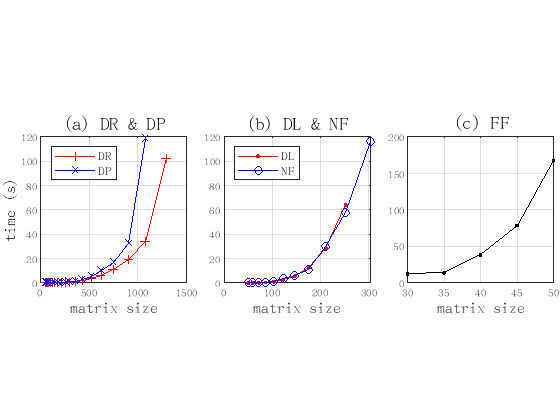

xDR = [50 60 72 86 103 123 147 176 211 253 303 363 435 522 626 751 901 1081 1297];
yDR = [0.01 0 0.01 0.01 0.02 0.04 0.06 0.1 0.17 0.3 0.52 0.96 1.77 3.35 6.25 11.02 19.56 33.99 101.93];
xDP = [50 60 72 86 103 123 147 176 211 253 303 363 435 522 626 751 901 1081];
yDP = [0.01 0.01 0.01 0.02 0.03 0.05 0.09 0.16 0.27 0.47 0.84 1.54 2.92 5.44 9.91 16.82 32.41 118.78];
xDL = [50 60 72 86 103 123 147 176 211 253];
yDL = [0.07 0.12 0.26 0.52 1.06 2.62 5.63 12.77 28.51 64.28];
xNF = [50 60 72 86 103 123 147 176 211 253 303];
yNF = [0.07 0.13 0.29 0.59 1.25 3.59 6.47 10.79 29.62 57.65 116.23];
xFF = [30 35 40 45 50];
yFF = [12.54 13.70 38.38 78.69 167.92];

t=tiledlayout(1,3);
t.TileSpacing='compact';
t.Padding='tight';

% (1,2): DR vs DP
t1=nexttile;
plot(xDR,yDR,'r+-', xDP,yDP,'bx-');
grid('on')
legend({'DR','DP'}, 'fontsize', 10, 'Location','northwest');
title('(a) DR & DP', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
ylabel('time (s)', 'fontsize', 12);
pbaspect([1 1 1]) % Control relative lengths of each axis

% (1,3): DL vs NF
t2=nexttile;
plot(xDL,yDL,'r.-', xNF,yNF,'bo-');
grid('on')
% str = {'DL', 'NF'};
legend({'DL', 'NF'}, 'fontsize', 10, 'Location','northwest');
title('(b) DL & NF', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
% ylabel('time (s)', 'fontsize', 10);
pbaspect([1 1 1]) % Control relative lengths of each axis

% (1,1): FF
t3=nexttile;
plot(xFF,yFF,'k.-')
grid('on')
title('(c) FF', 'fontsize', 14);
xlabel('matrix size', 'fontsize', 12);
% ylabel('time (s)', 'fontsize', 12);
pbaspect([1 1 1]) % Control relative lengths of each axis


% output
% fig = gcf;
% fig.PaperPositionMode = 'auto';
% fig_pos = fig.PaperPosition;
% fig.PaperSize = [fig_pos(3) fig_pos(4)];
% print('-painters','-dpdf','-r600','test')
